# Linear Control Design 2 - Fall 2019 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E19) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E19'

Exam = 'LCD2 E19'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Optimal control of an active suspension system

The suspension system is a key component of the vehicle directly affecting the passenger comfort and the ability of the vehicle itself to hold the road. In active suspension system an actuator is positioned between the sprung mass of the vehicle and the unsprung mass (wheel, tyre, brake, etc.) parallel to the suspension elements with the objective of pulling/pushing the vehicle body in order to suppress the vibrations due to road irregularities.

### Quarter-car suspension system

The system dynamics of a suspension system for a single wheel is descibed by

$m_s\ddot{z}_s = -b_s(\dot{z}_s-\dot{z}_u) - k_s(z_s-z_u) + f_a \\
m_u\ddot{z}_u = b_s(\dot{z}_s-\dot{z}_u) + k_s(z_s-z_u) - f_a + b_t(\dot{z}_r-\dot{z}_u) + k_t(z_r-z_u)$           (1)

where

- $m_s, \, b_s, \, k_s$ are the mass, damping and stiffness of the sprung element (quarter-car)

- $m_u, \, b_t, \, k_t$ are the mass, damping and stiffness of the unsprung element (wheel-tyre-brake)

- $z_s$ is the displacement of the sprung element

- $z_u$ is the displacement of the unsprung element

- $z_r$ is the displacement of the road

- $f_a$ is the force exerted by an hydraulic actuator placed between the sprung and unsprung elements

The applied force on the tyre from the road 

$f_d =  b_t\dot{z}_r + k_tz_r$                                                               (2)

is considered as an unknown disturbance in the sytem, which should be properly handled by the active suspension. Based on this, the system dynamics in Eq. (1) can be rewritten as

$m_s\ddot{z}_s = -b_s(\dot{z}_s-\dot{z}_u) - k_s(z_s-z_u) + f_a \\
m_u\ddot{z}_u = b_s(\dot{z}_s-\dot{z}_u) + k_s(z_s-z_u) - b_t\dot{z}_u - k_tz_u - f_a +f_d$     (3)

The following figure details the schematic of the system with all the relevant quantities.

 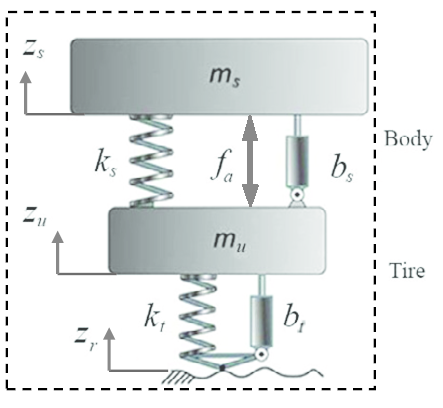

The linear model in Eq. (1) is implemented in the Simulink file QuarterCar_ActiveSusp_SimulinkYYYYC, where YYYYC refers to the Simulink version (2019b, 2019a, 2018b, 2018a, 2017b, 2017a, 2016b, 2016a). The numerical values for the model parameters are provided right below.

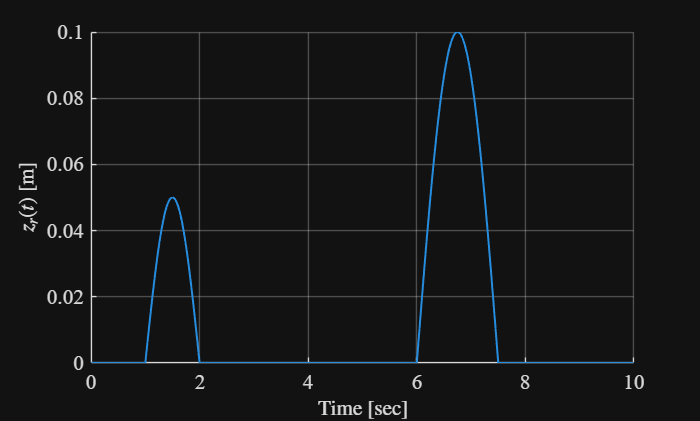

clc; clear;
% Model paramters (RG)
% System parameters
m_s = 243; % sprung mass [kg]
m_u = 40; % unsprung mass [kg]
b_s = 370; % damping coefficient [N*s/m]
b_t = 414; % tyre damping coefficient [N*s/m]
k_s = 14761; % stiffness coefficient [N/m]
k_t = 124660; % tyre stiffness coefficient [N/m]

% Road profiles for open and closed-loop simulations (RG)
load road_profile.mat
time_det = time_det'; % column vector
time_stc = time_stc'; % column vector
z_r_det = z_r_det'; % column vector
z_r_stc = z_r_stc'; % column vector
% two road profiles are included:
% [t_det,z_r_det,z_r_dot_det] - deterministic road profile where t_det is the
% travelling time, z_r_det is the vertical road displacement and z_r_dot_det
% is the rate of change of the road profile.
% [t_stc,z_r_stc,z_r_dot_stc] - stochastic road profile where t_stc is the
% travelling time, z_r_stc is the vertical road displacement and z_r_dot_stc 
% is the rate of change of the road profile.
% Both profiles have been generated for a car traveling with a forward
% speed of 40 km/h

% Plot road profiles (RG)
% Deterministic road profile
figure, h1 = axes; set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_r_det,'LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$z_r(t)$ [m]','FontName','times','FontSize',16,'Interpreter','latex')

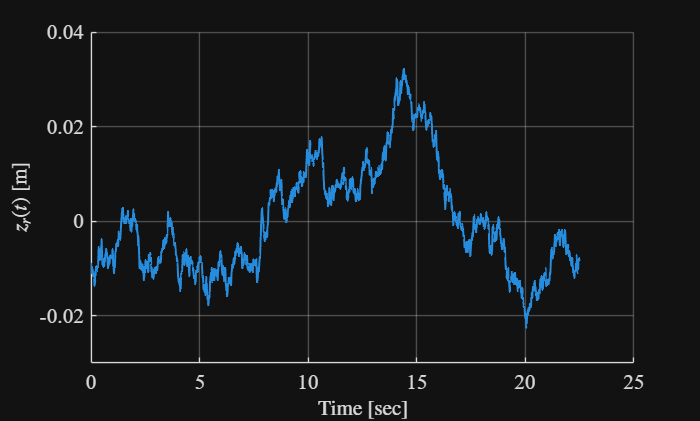

% Stochastic road profile
figure, h2 = axes; set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time_stc,z_r_stc,'LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$z_r(t)$ [m]','FontName','times','FontSize',16,'Interpreter','latex')

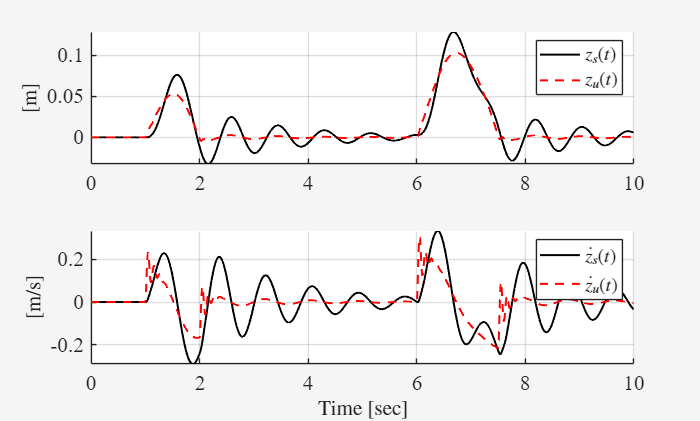

% Test the provided active suspension model on deterministic road profile (RG)
SIM_TIME = time_det(end); % simulation time (can be changed as needed)
STEP_SIZE = 0.01; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'QuarterCar_ActiveSusp_Simulink2018b';
f_a = zeros(length(time_det),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time_det f_a z_r_det z_r_dot_det])

% Plot the temporal behaviour of the state variables
z_s = logsout.getElement('z_s').Values.Data;
z_s_dot = logsout.getElement('z_s_dot').Values.Data;
z_u = logsout.getElement('z_u').Values.Data;
z_u_dot = logsout.getElement('z_u_dot').Values.Data;

figure, h5 = subplot(2,1,1); set(h5,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s,'k',time_det,z_u,'--r','LineWidth',1.5)
ylabel('[m]','FontName','times','FontSize',16,'Interpreter','latex')
leg1 = legend('$z_s(t)$','$z_u(t)$');
set(leg1,'FontName','times','FontSize',14,'Interpreter','latex')
h6 = subplot(2,1,2); set(h6,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s_dot,'k',time_det,z_u_dot,'--r','LineWidth',1.5)
ylabel('[m/s]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg2 = legend('$\dot{z}_s(t)$','$\dot{z}_u(t)$');
set(leg2,'FontName','times','FontSize',14,'Interpreter','latex')
theme("light")

### Open-loop system analysis

**Problem 1 [2 points]** Based on the system dynamics described in Eq. (3), set up the linear state space model of the system.

% Your solution goes here
A = [0 1 0 0; -k_s/m_s -b_s/m_s k_s/m_s b_s/m_s; ...
     0 0 0 1; k_s/m_u b_s/m_u -(k_s+k_t)/m_u -(b_s+b_t)/m_u];
B = [0 1/m_s 0 -1/m_u]';
Bv = [0 0 0 1/m_u]';
C = [-k_s/m_s -b_s/m_s k_s/m_s b_s/m_s];
D =  1/m_s;
Dv = 0;

act_susp = ss(A,[B Bv],C,[D Dv])


act_susp =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  -60.74  -1.523   60.74   1.523
   x3       0       0       0       1
   x4     369    9.25   -3486   -19.6
 
  B = 
             u1        u2
   x1         0         0
   x2  0.004115         0
   x3         0         0
   x4    -0.025     0.025
 
  C = 
           x1      x2      x3      x4
   y1  -60.74  -1.523   60.74   1.523
 
  D = 
             u1        u2
   y1  0.004115         0
 
Continuous-time state-space model.


**Problem 2 [2 points]** Evaluate the internal and the external stability of system.

% Your solution goes here
eig(A)

ans =   -9.9451 +58.1744i
  -9.9451 -58.1744i
  -0.6162 + 7.3465i
  -0.6162 - 7.3465i


Negative real parts, so the system is internally and externally stable.

### Control system design for vibration damping

The main control objectives are to improve the passenger comfort and vehicle handling in the presence of road profile variations by actively damping the introduced vibrations. The passenger comfort is evaluated in terms of vertical acceleration $\ddot{z}_s$ experienced by the sprung mass; whereas the vehicle handling is evaluated in terms of tire deflection $(z_u-z_r)$ and suspension deflection $(z_s-z_u)$.

Closed-loop system requirements

When subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$ the closed-loop system is expected to fulfil the following requirements

- The peak of the vertical acceleration $\ddot{z}_s$ of the sprung mass is reduced by 20-40% in comparison to the peak displayed in open-loop (passive suspension)

- The vertical acceleration $\ddot{z}_s$ of the sprung mass settles to zero within 2-4 seconds since the time a road bump hits the tire

- The control effor $f_a$ is kept within $\pm1\,kN$

**Problem 3 [2 points]** Assess the open-loop characteristics of the

- vertical acceleration $\ddot{z}_s$

- tire deflection $(z_u-z_r)$

- suspension deflection $(z_s-z_u)$

when the system is subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$ in terms of largest deviation from the rest position, decay rate and settling time.

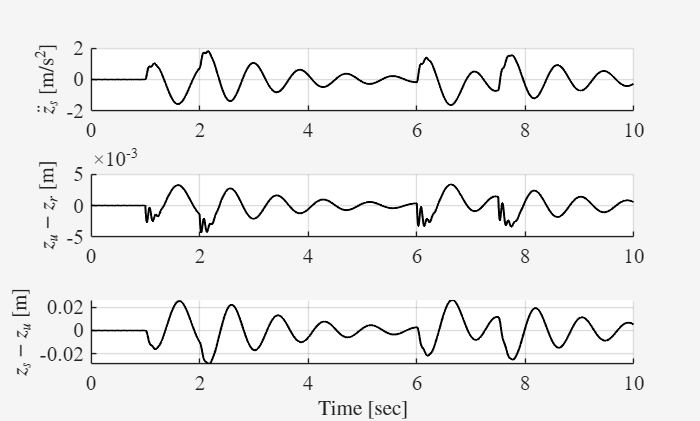

% Your solution goes here
% Plot the temporal behaviour of 
%   *   vertical accelaration
%   *   tire deflection
%   *   suspension deflection

z_s = logsout.getElement('z_s').Values.Data;
z_s_dot = logsout.getElement('z_s_dot').Values.Data;
z_s_ddot = logsout.getElement('z_s_ddot').Values.Data;
z_u = logsout.getElement('z_u').Values.Data;
z_u_dot = logsout.getElement('z_u_dot').Values.Data;

tire_defl = z_u - z_r_det;
susp_defl = z_s - z_u;

figure, h6 = subplot(3,1,1); set(h6,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s_ddot,'k','LineWidth',1.5)
ylabel('$\ddot{z}_s$ [m/s$^2$]','FontName','times','FontSize',16,'Interpreter','latex')
h7 = subplot(3,1,2); set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,tire_defl,'k','LineWidth',1.5)
ylabel('$z_u -z_r$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h8 = subplot(3,1,3); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,susp_defl,'k','LineWidth',1.5)
ylabel('$z_s-z_u$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
theme("light")


max_z_s_ddot = max(abs(z_s_ddot));
disp('The maximum peak of the vertical acceleration in open loop is [m/s^2]:')

The maximum peak of the vertical acceleration in open loop is [m/s^2]:


disp(max_z_s_ddot)

    1.7917



max_tire_defl = max(abs(tire_defl));
disp('The maximum peak of the tire deflection in open loop is [m]:')

The maximum peak of the tire deflection in open loop is [m]:


disp(max_tire_defl)

    0.0043




max_susp_defl = max(abs(susp_defl));
disp('The maximum peak of the suspension deflection in open loop is [m]:')

The maximum peak of the suspension deflection in open loop is [m]:


disp(max_susp_defl)

    0.0289



An estimate of the decay rate and settling time can be obtained through the analysis of the system eigenvalues

[wn,zeta] = damp(A)

wn =    59.0183
   59.0183
    7.3723
    7.3723


zeta =     0.1685
    0.1685
    0.0836
    0.0836


T_osc = 2*pi./[wn(1) wn(3)] % periods of oscialltory modes

T_osc =     0.1065    0.8523


**Problem 4 [6 points]** Under the assumption that the state is fully accessible design a discrete time optimal controller that meets the aforementioned specifications using the linear quadratic regulator approach.

% Your solution goes here
% No reference tracking or integral action. Just want to stabilize
% acceleration to 0 asap
Mc = ctrb(A,B);
if rank(Mc) == size(A,1)
    disp('Open loop linear system is controllable')
else
    disp('Open loop linear system is not controllable')
end

Open loop linear system is controllable



Ts = 0.01;
[F,G] = c2d(A,B,Ts);
[~,Gv] = c2d(A,Bv,Ts);
Q = diag([100 0.1 100 0.1]);
R = 1/(750)^2; % maximum force is 1kN hence the weight is chosen using 75% of total maximum force;

[K_lqr,~,lambda_cl_dt] = dlqr(F,G,Q*Ts,R*Ts);
abs(lambda_cl_dt)

ans =     0.9805
    0.9805
    0.9004
    0.9004


**Problem 5 [2 points]** Implement the discrete time optimal controller in the given Simulink diagram and evalute the closed-loop system performance against the open-loop one, when the sytem is subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$. Verify that the closed-loop requirements are fulfilled.

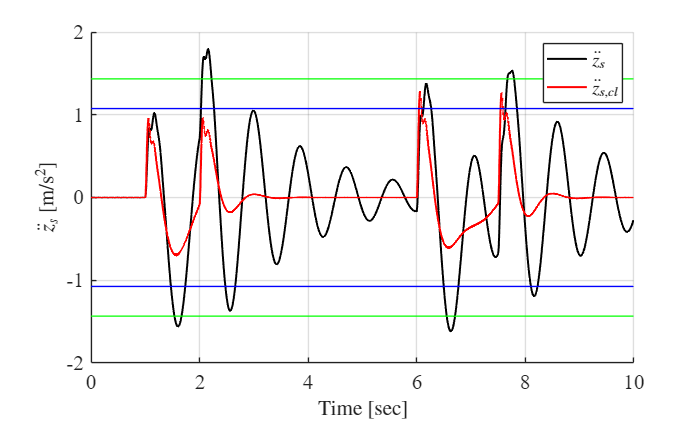

% Your solution goes here
STEP_SIZE = 0.005; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'QuarterCar_ActiveSusp_DLQR_Simulink2018b';
sim(SIMULINK_FILENAME,SIM_TIME,[],[time_det z_r_det z_r_dot_det])

% Plot the temporal behaviour of the state variables
time_sim = logsout.getElement('z_s').Values.Time;
z_s_cl = logsout.getElement('z_s').Values.Data;
z_s_dot_cl = logsout.getElement('z_s_dot').Values.Data;
z_s_ddot_cl = logsout.getElement('z_s_ddot').Values.Data;
z_u_cl = logsout.getElement('z_u').Values.Data;
z_u_dot_cl = logsout.getElement('z_u_dot').Values.Data;
z_r_sim = logsout.getElement('z_r').Values.Data;
z_r_dot_sim = logsout.getElement('z_r_dot').Values.Data;
f_a = logsout.getElement('f_a').Values.Data;

tire_defl_cl = z_u_cl - z_r_sim;
susp_defl_cl = z_s_cl - z_u_cl;

max_peak_vert_acc_20 = 0.8*max_z_s_ddot; 
max_peak_vert_acc_40 = 0.6*max_z_s_ddot;

figure, h6 = axes; set(h6,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s_ddot,'k',time_sim,z_s_ddot_cl,'-r','LineWidth',1.5)
line([time_det(1) time_det(end)],[max_peak_vert_acc_20 max_peak_vert_acc_20],'Color','g','LineWidth',1)
line([time_det(1) time_det(end)],[max_peak_vert_acc_40 max_peak_vert_acc_40],'Color','b','LineWidth',1)
line([time_det(1) time_det(end)],-[max_peak_vert_acc_20 max_peak_vert_acc_20],'Color','g','LineWidth',1)
line([time_det(1) time_det(end)],-[max_peak_vert_acc_40 max_peak_vert_acc_40],'Color','b','LineWidth',1)
ylabel('$\ddot{z}_s$ [m/s$^2$]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
legend({'$\ddot z_s$', '$\ddot z_{s,cl}$'}, 'interpreter', 'latex')
theme("light")

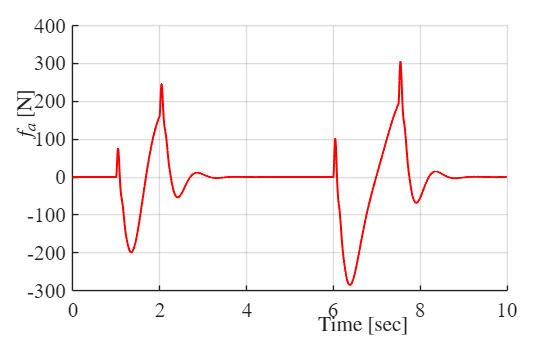

figure, h9 = axes; set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,f_a,'-r','LineWidth',1.5)
ylabel('$f_a$ [N]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
theme("light")

max_z_s_ddot_cl = max(abs(z_s_ddot_cl));
disp('The maximum peak of the vertical acceleration in open loop is [m/s^2]:')

The maximum peak of the vertical acceleration in open loop is [m/s^2]:


disp(max_z_s_ddot_cl)

    1.2756



if max_z_s_ddot_cl <= max_peak_vert_acc_20 && max_z_s_ddot_cl >= max_peak_vert_acc_40
    disp('Damping requirement is fulfilled and the peak reduction is')
    damp_red = (max_z_s_ddot - max_z_s_ddot_cl)/max_z_s_ddot*100;
    disp(strcat(num2str(damp_red),'%'))
else
    disp('Damping requirement is not fulfilled and the peak reduction is')
    damp_red = (max_z_s_ddot - max_z_s_ddot_cl)/max_z_s_ddot*100;
    disp(strcat(num2str(damp_red),'%'))
end

Damping requirement is fulfilled and the peak reduction is


28.8061%


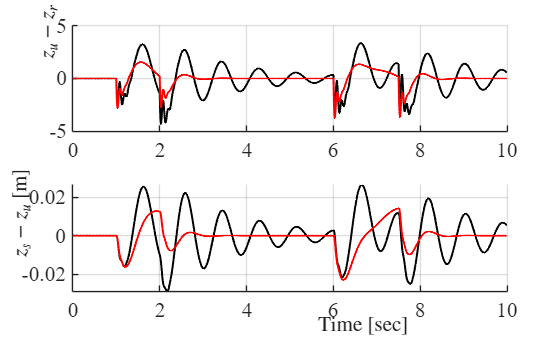

figure, h7 = subplot(2,1,1); set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,tire_defl,'k',time_sim,tire_defl_cl,'-r','LineWidth',1.5)
ylabel('$z_u -z_r$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h8 = subplot(2,1,2); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,susp_defl,'k',time_sim,susp_defl_cl,'-r','LineWidth',1.5)
ylabel('$z_s-z_u$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
theme("light")

### State estimation for output feedback control

In order to implement an output feedback controller for the active suspension, the state vector must be estimated based on available measurements. For the active suspension a common measurement easy to implement is the measurement of the acceleration of the sprung mass, i.e. $\ddot{z}_s$. Therefore in the last part of the exercise, we assume that the following measurement is available

$y_1 = \ddot{z}_s + v_1$                                                                   (4)

where $v_1$ is white noise with zero mean and noise intensity $I_{\ddot{z}_s} = 6.25\times10^{-4} \, m^2/s^4$. 

In the resolution of the following problems it is assumed that the system dynamics Eq. (3) is subject to the stochastic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{stc}$.

**Problem 6 [6 points]** Under the assumption that the disturbance $f_d$ is unknown, design a discrete time Kalman filter able to reconstruct the state vector $\mathbf{x}= [z_s, \dot{z}_s,z_u,\dot{z}_u]^\mathrm{T}$.

% Your solution goes here
F_kf = F; % Gdol (disturbance matrix Bv) gets added, as disturbance is now a state
G_kf = G;
Bv_kf = [0; 0; 1]; % continuous time process noise input matrix
Gn = eye(4); % discrete time process noise input matrix
C_kf = C;

% Check observability
Mo = obsv(F_kf,C_kf);
if rank(Mo) == size(F_kf,1)
    disp('The open loop system is observable')
end

The open loop system is observable


% Process noise
V1 = diag([0.0001 0.005 0.0001 5e-6]);
Bn = [1 0 0 0;0 k_s/m_s 0 0;0 0 1 0;0 0 0 k_t/m_u];
V1d = Bn * V1 * Bn' * Ts;

% Measurement nosie
I_zs_ddot = 6.25*10^(-4);
V2d = I_zs_ddot / Ts;

[L_kf,P_kf,Z,lambda_ee_dt] = dlqe(F_kf, Bn, C_kf, V1d, V2d)

L_kf =    -0.0015
   -0.0043
   -0.0011
    0.6362


P_kf = 1.0e+06 *

    0.0005    0.0013    0.0004   -0.0045
    0.0013    0.0160    0.0010   -0.0036
    0.0004    0.0010    0.0003   -0.0033
   -0.0045   -0.0036   -0.0033    4.7625


Z = 1.0e+04 *

    0.0483    0.1249    0.0352    0.6496
    0.1249    1.5810    0.0951    2.7685
    0.0352    0.0951    0.0256    0.4764
    0.6496    2.7685    0.4764    9.6785


lambda_ee_dt =    0.9721 + 0.0473i
   0.9721 - 0.0473i
   0.5014 + 0.0000i
   0.0000 + 0.0000i


abs(lambda_ee_dt) % Stable

ans =     0.9733
    0.9733
    0.5014
    0.0000


**Problem 7 [4 points]** Implement the discrete time Kalman filter in the Simulink diagram of the open-loop system and assess its estimation performance when the open-loop system is subject to the stochastic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{stc}$

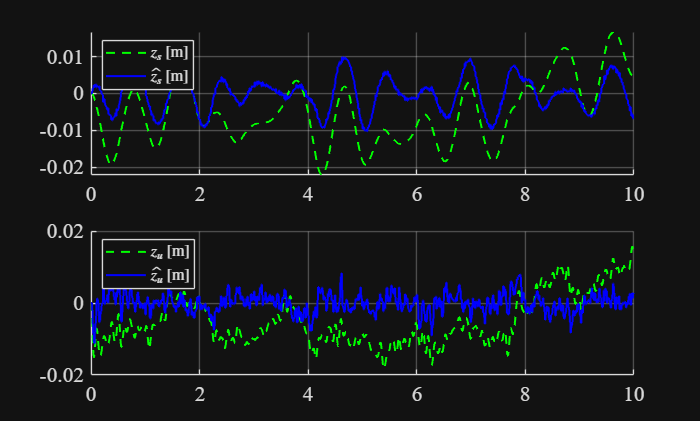

% Your solution goes here
SIMULINK_FILENAME = 'QuarterCar_ActiveSusp_KF_Simulink2018b';
x0hat = zeros(4,1);
A_f = 0; % amplitude of the force [N]
w_f = 2*pi*2; % frequency of the force [rad/s]
f_a = A_f*sin(w_f*time_stc);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time_stc z_r_stc z_r_dot_stc f_a])

% Plot the temporal behaviour of the state variables
time_sim = logsout.getElement('z_s').Values.Time;
z_s = logsout.getElement('z_s').Values.Data;
z_s_dot = logsout.getElement('z_s_dot').Values.Data;
z_s_ddot = logsout.getElement('z_s_ddot').Values.Data;
z_u = logsout.getElement('z_u').Values.Data;
z_u_dot = logsout.getElement('z_u_dot').Values.Data;
xhat = logsout.getElement('xhat').Values.Data;
yhat = logsout.getElement('yhat').Values.Data;
y = logsout.getElement('y').Values.Data;
f_a = logsout.getElement('f_a').Values.Data;
timeDT = logsout.getElement('xhat').Values.Time;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time_sim,z_s,'--g','MarkerSize',4,'MarkerFaceColor','r','LineWidth',1.5)
stairs(timeDT,xhat(:,1),'b','LineWidth',1.5)
leg1 = legend('$z_s$ [m]','$\hat{z_s}$ [m]','Location','NorthWest');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time_sim,z_u,'--g','MarkerSize',4,'MarkerFaceColor','r','LineWidth',1.5)
stairs(timeDT,xhat(:,3),'b','LineWidth',1.5)
leg2 = legend('$z_u$ [m]','$\hat{z_u}$ [m]','Location','NorthWest');
set(leg2,'FontName','times','FontSize',12,'Interpreter','latex')

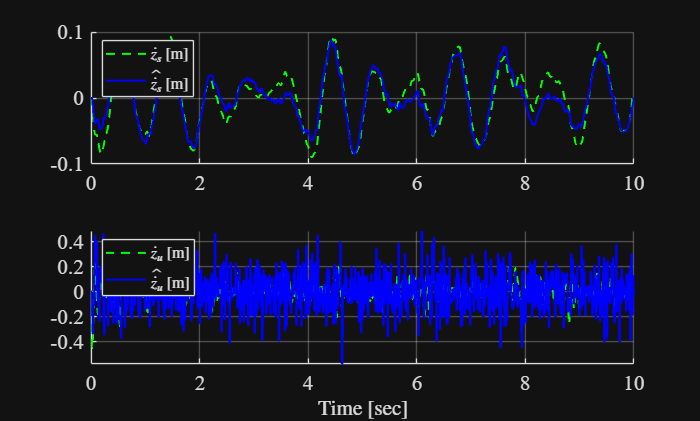


figure, h3 = subplot(2,1,1); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(time_sim,z_s_dot,'--g','LineWidth',1.5)
stairs(timeDT,xhat(:,2),'b','LineWidth',1.5)
leg3 = legend('$\dot{z}_s$ [m]','$\hat{\dot{z}_s}$ [m]','Location','NorthWest');
set(leg3,'FontName','times','FontSize',12,'Interpreter','latex')

h4 = subplot(2,1,2); set(h4,'FontName','times','FontSize',16)
hold on, grid on
plot(time_sim,z_u_dot,'--g','LineWidth',1.5)
stairs(timeDT,xhat(:,4),'b','LineWidth',1.5)
leg4 = legend('$\dot{z}_u$ [m]','$\hat{\dot{z}_u}$ [m]','Location','NorthWest');
set(leg4,'FontName','times','FontSize',12,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

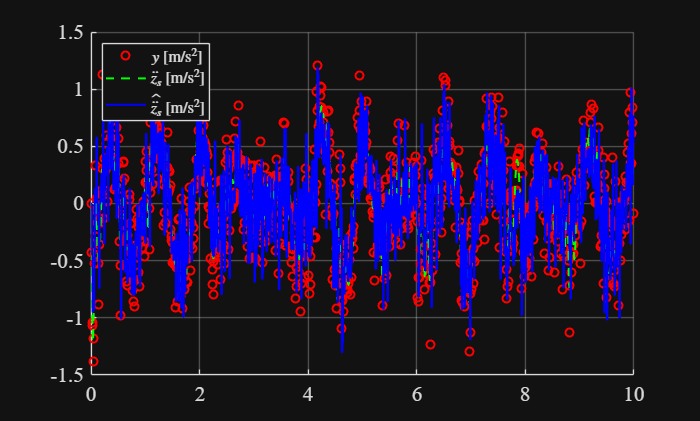


z_s_ddot_hat = f_a/m_s -k_s/m_s*xhat(:,1) -b_s/m_s*xhat(:,2) + k_s/m_s*xhat(:,3) + b_s/m_s*xhat(:,4);

figure, h5 = axes; set(h5,'FontName','times','FontSize',16)
hold on, grid on
plot(timeDT,y,'or',time_sim,z_s_ddot,'--g','LineWidth',1.5)
stairs(timeDT,z_s_ddot_hat,'b','LineWidth',1.5)
leg5 = legend('$y$ [m/s$^2$]','$\ddot{z}_s$ [m/s$^2$]','$\hat{\ddot{z}_s}$ [m/s$^2$]','Location','NorthWest');
set(leg5,'FontName','times','FontSize',12,'Interpreter','latex')